# Lab session II:

## Intro:

On this Laboratory session we are going to work with the different attitude representations seen in class. 

- Exercise 1: 1 point.

- Exercise 2: 2 points

- Exercise 3: 2.5 points

- Exercise 4: 2 points

- Exercise 5: 2.5 points

**Lab rules:**

- Always respect the delivery dates

- Use the templates when provided and DO NOT MODIFY THE FILE NAMES OR THE FUNCTION NAMES

- Verify that your code works before submit

- Always upload the files in a .zip with the name structure:  * Surname_Name.zip*

- Cheating is not allowed and will be firmly punished with a final mark of 0

This assignment is due to Sunday 22th before 23:45 p.m.

## Exercise 1:

**Create** and **test** a function named **Eaa2rotMat **that given euler axis/angle information returns the respective rotation matrix.

Perform and show the result of the next verifications:

- Calculate the determinant of the resulting rotation matrix 

angle = 45;
axis = [0; 0; 1];

R = Eaa2RotMatrix(angle, axis)

R =     0.7071   -0.7071         0
    0.7071    0.7071         0
         0         0    1.0000


detR = det(R)

detR = 1.0000

- Compare the transpose and the inverse of the resulting matrix

R'

ans =     0.7071    0.7071         0
   -0.7071    0.7071         0
         0         0    1.0000


inv(R)

ans =     0.7071    0.7071         0
   -0.7071    0.7071         0
         0         0    1.0000


- Using the output matrix, transform a vector parallel to the axis of rotation. 

parallel = [0; 0; 2];
trans_parallel = R * parallel

trans_parallel =      0
     0
     2


What happens?

    El vector no canvia ja que rota sobre sí mateix.

- Using the output matrix, transform a vector perpendicular to the axis direction. Calculate the escalar product between the original  vector and the transformed one.

perpendicular = [0; 1; 0];
trans_perpendicular = R * perpendicular

trans_perpendicular =    -0.7071
    0.7071
         0


escalar = dot(perpendicular, trans_perpendicular)

escalar = 0.7071

 What you observe?

    L'escalar és el cosinus de l'angle que hem fet servir per crear la matriu ja que els vectors que hem fet servir són unitaris.

## Exercise 2:

The matrix 

axisM = (rand(3,100)-.5);

 contains 100 random (non-unit) axis. While 

theta = linspace(0,6*pi,100);

 is a vector with orderer angles.

Every pair, axisM(:,q) and theta(q) represents the attitude of a body.

- For every pair theta-axis, (in a for loop) calculate the rotation matrix and store the value of its trace in a vector.

- Make a plot of the trace that you have obtained vs the theta angle. Explain what you observe.

               * Explanation Here:*

## Exercise 3:

**Create** and **test** a function named **rotMat2Eaa** that given a rotation matrix returns its respective euler principal axis and angle.

Perform and show the results of the next verifications:

- Use the function on exercise 1 to create a rotation matrix from Euler axis information and ensure that the new function performs the inverse mapping correctly.

[ea, eaxis] = rotMat2Eaa(R);
ea

ea = 45.0000

eaxis

eaxis =          0         0    1.0000


- What happens if you try to extract the angle and axis of the next matrices? What they have in common? 


$$\mathbf{R}_1 = \left( \begin{array}{ccc} 1 &0 &0\\ 0 &1&0 \\0 &0 & 1\end{array}\right),$$

$$\mathbf{R}_2 = \left( \begin{array}{ccc} -\frac{1}{3} &\frac{2}{3} &\frac{2}{3}\\ \frac{2}{3} &-\frac{1}{3}&\frac{2}{3} \\\frac{2}{3} &\frac{2}{3} & -\frac{1}{3}\end{array}\right),$$

$$\mathbf{R}_3 = \left( \begin{array}{ccc} 0 &0 &-1\\ 0 &-1&0 \\-1 &0 & 0\end{array}\right),$$


*            Aquestes matrius són simètriques i per tant R - R' = 0 i sin(angle) = 0. Fent servir la matriu esquiosimètrica no podem obtenir l'eix de rotació.*

*            Solució:*

*            En el primer cas l'angle és 0 i per tant la rotació s'ha pogut realitzar al voltant de qualsevol eix. Per això establim un eix "neutral" perquè la funció                el retorni quan es doni el cas que angle == 0. En el nostre cas axis = [1;0;0] (l'eix X de base canònica).*

*            En els dos últims casos l'angle és 180 i la funció ha de retornar un eix fet a partir de la fórmula de Rodrigues per theta == pi*

- Propose a solution for the past problem, **implement it** and verify that it works using the past matrices

*Solution here : *

R1 = [1 0 0; 0 1 0; 0 0 1];
R2 = [-1/3 2/3 2/3; 2/3 -1/3 2/3; 2/3 2/3 -1/3];
R3 = [0 0 -1; 0 -1 0; -1 0 0];

[R1ea, R1eaxis] = rotMat2Eaa(R1)

R1ea = 0

R1eaxis =      1
     0
     0


[R2ea, R2eaxis] = rotMat2Eaa(R2)

R2ea = 180

R2eaxis =     0.5774    0.5774    0.5774


[R3ea, R3eaxis] = rotMat2Eaa(R3)

R3ea = 180

R3eaxis =     0.7071         0    0.7071


## Exercise 4

**Find the rotation vectors** that rotates the cube to reach the next orientations:

- The green face points in the positive z direction and the orange face in the -y direction

-     $$r_1 = $$ ( , , )$$^T$$

- The orange face points in the -z direction and the blue face into the +y direction

-     $$r_2 = $$ ( , , )$$^T$$

- The red face points on the -x direction and the blue face into the -y direction

-     $$r_3 = $$ ( , , )$$^T$$

Use the function of the exercise 1 transform the orientation of the cube given by M for **every** of the previous cases and use the function  Cubeplot to  verify your previous answers

M = [    -1  -1 1;   %Node 1
    -1   1 1;   %Node 2
    1   1 1;   %Node 3
    1  -1 1;   %Node 4
    -1  -1 -1;  %Node 5
    -1   1 -1;  %Node 6
    1   1 -1;  %Node 7
    1  -1 -1]; %Node 8


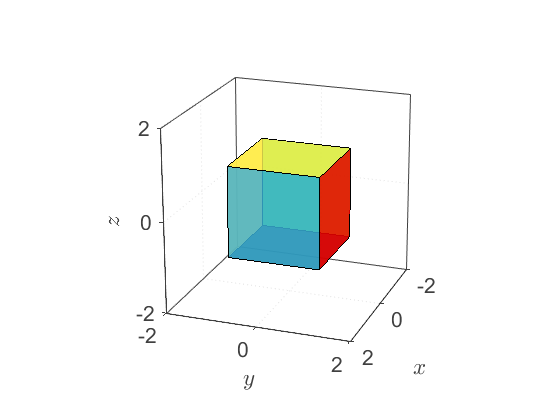

R = eye(3);
M_mod = (R*M')';
Cubeplot(M_mod);

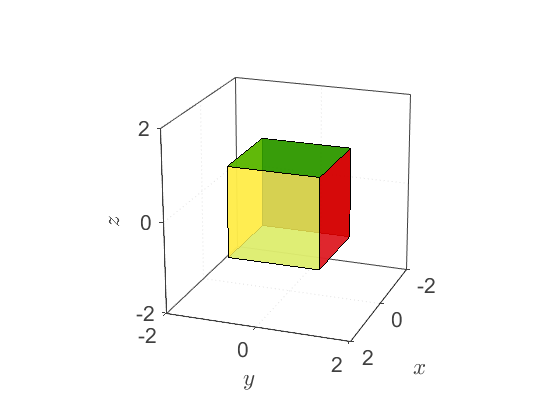

%R1
r1 = [0; 1; 0];
R = Eaa2RotMatrix(90, r1);

M_mod = (R*M')';
Cubeplot(M_mod);

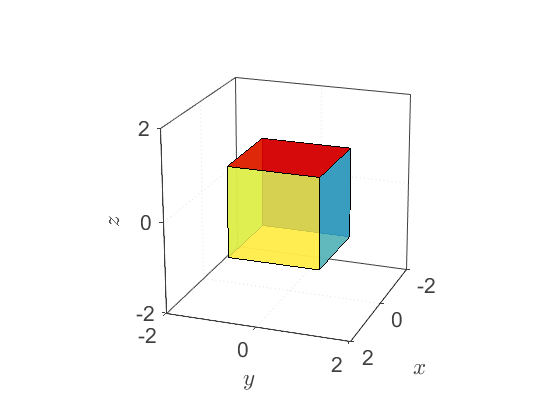

%R2
r2first = [1; 0; 0];
r2second = [0; 0; 1];
R2first = Eaa2RotMatrix(90, r2first);
R2second = Eaa2RotMatrix(90, r2second);

R = R2second * R2first;

M_mod = (R*M')';
Cubeplot(M_mod);

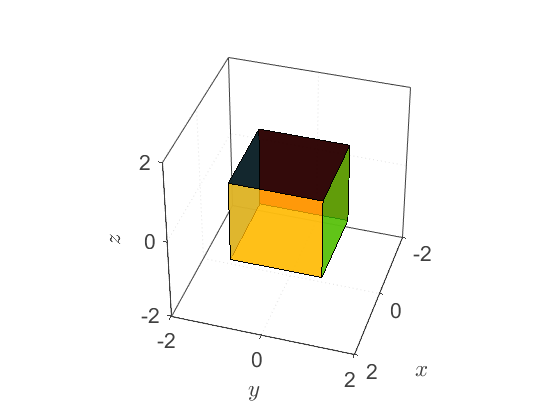

%R3
r3first = [0; 0; 1];
r3second = [1; 0; 0];
R3first = Eaa2RotMatrix(90, r3first);
R3second = Eaa2RotMatrix(180, r3second);

R = R3second * R3first;

M_mod = (R*M')';
Cubeplot(M_mod);

## Exercise 5

**Create** and **test **a function named **eAngles2rotM **that given a set of euler angles $(\varphi, \theta, \psi)$, return its respective rotation matrix.

- Calculate the determinant of the resulting rotation matrix 

- Compare the transpose and the inverse of the resulting matrix

**Create also** a function named **rotM2eAngles **that given a rotation matrix return its respective euler angles

- Ensure that the case for which theta = pi/2 + k*pi with k=1,2,.. is well implemented. You can set phi = 0 if you need it.

- Use the first function of this exercise to create a rotation matrix from a set of euler angles and ensure that the new function performs the inverse mapping correctly.